# Numerical Methods Assignment 3

Group XX

Name1 StudentNumber1

Name2 StudentNumber2

Name3 StudentNumber3

**Instructions:**

- Submit the assignment by the deadline on Monday October 19 at 14:00 via Brightspace. All group members must be enrolled in the group before the assignment is submitted.

- **Submit two files: this .mlx file and an .pdf export of the same file. Save both files as NM_AS3_GroupX.mlx and NM_AS3_GroupX.pdf, replacing the X by your group number.**

- Ensure your group number, names and student numbers are at the top of the document.

- **Consult the course description for details** on the assignment, including information on the discussion and the generative AI policy.

- Include a statement on the ways in which you used generative AI, if any, in the box below. If you worked individually, ensure every group members writes their own statement.

- This type of MATLAB file is called a Live Code File Format (.mlx). It allows you to have all code in one place, and show code, generated figures, text, and equations all next to eachother. It is fairly self-explanatory, but this page and links within it provide some further explanation: [http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.](http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.) You are welcome to remove the text of the assignment or keep it and add in your solutions. 

## Generative AI statement

*Explain here how you used generative AI, if any, for this assignment. If you worked individually, use a separate statement for each group member.*

## Set-up Problem 1 (12 pts.)

The main functions you will use in Problem 1 are the following. Define the functions here, paying attention to efficient implementation. Ensure you call these functions when solving problem 1. You may not use built-in ODE solvers throughout problem 1.

% Implementation of explicit Euler
function [t, x] = explicit_euler(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));

x(:, it) = x0;

for n = 1:(length(t)-1)
    x1 = x(:, it) + h * f(t(it), x(:, it));
    it = it + 1;
    x(:, it) = x1;
end
end

% Implementation of Improved Euler
function [t, x] = improved_euler(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));

x(:, it) = x0;

for n = 1:(length(t)-1)
    predictor = x(:, it) + h * f(t(it), x(:, it));
    x1 = x(:, it) + h/2*(f(t(it), x(:, it)) + f(t(it+1), predictor));
    it = it + 1;
    x(:, it) = x1;
end
end

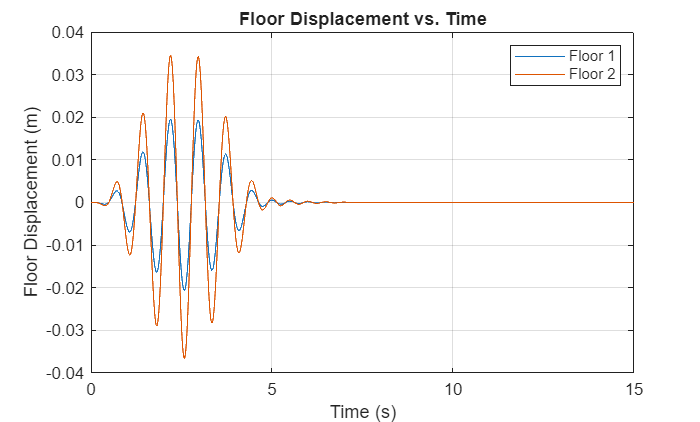

% Implementation of RK4
function [t, x] = RK4(f, x0, t0, h, tf)
it = 1;
t = t0:h:tf;
x = zeros(length(x0), length(t));

x(:, it) = x0;


for n = 1:(length(t)-1)

    k1 = f(t(it),           x(:, it));
    k2 = f(t(it) + h/2,     x(:, it) + (h/2)*k1);
    k3 = f(t(it) + h/2,     x(:, it) + (h/2)*k2);
    k4 = f(t(it) + h,       x(:, it) + h*k3);
    
    x1 = x(:, it) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);

    it = it + 1;
    x(:, it) = x1;
end
end

## Problem 1: Seismic Response of a Two-Story Building (50 pts)

A two-story building is subjected to horizontal ground motion during an earthquake. The building is modeled as a two-degree-of-freedom mass-spring-damper system.

Each floor is assumed to behave as a rigid mass, while the lateral stiffness and energy dissipation provided by the columns are represented by linear springs and viscous dampers.

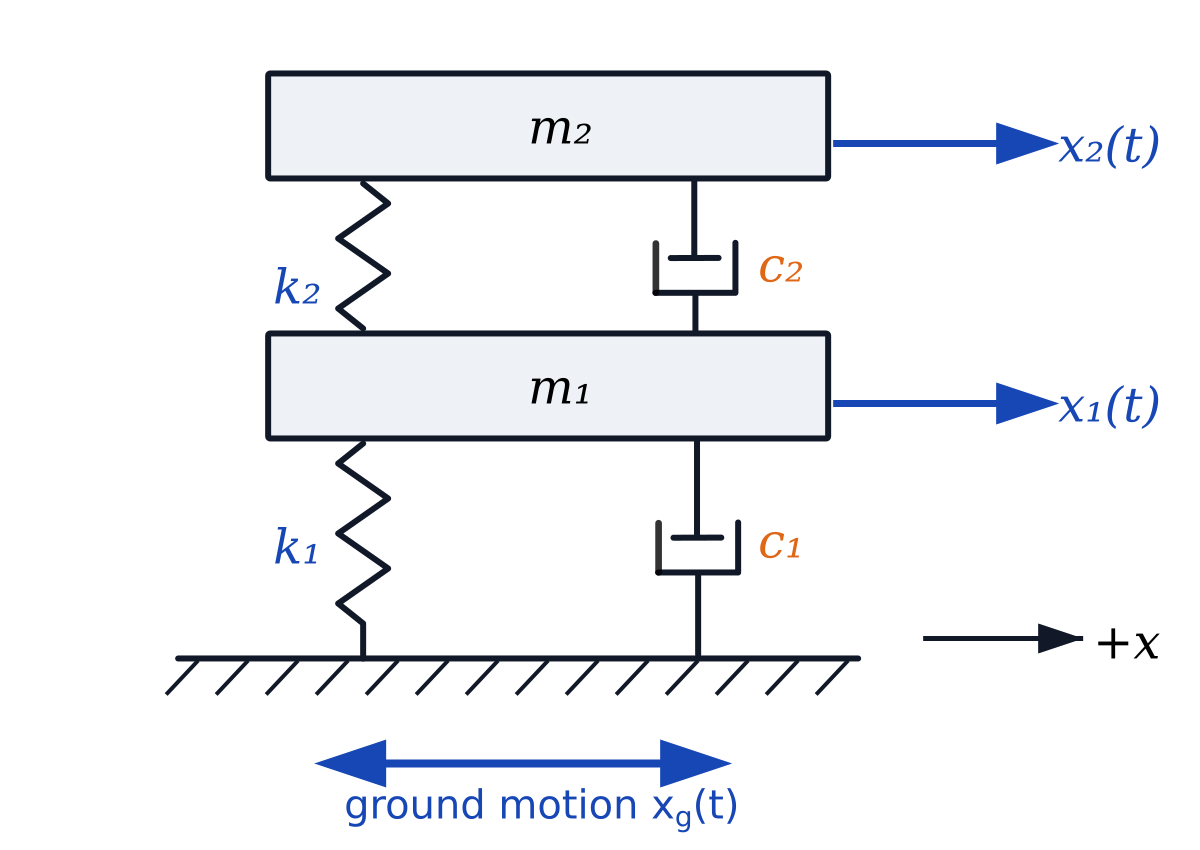

Let:

- $x_1(t)$ be the horizontal displacement of the first floor relative to the ground

- $x_2(t)$ be the horizontal displacement of the second floor relative to the ground

- $m_1$ and $m_2$ be the masses of the first and second floors

- $k_1$ and $k_2$ be the lateral stiffnesses of the first and second stories

- $c_1$ and $c_2$ be the corresponding viscous damping coefficients

- $x_g(t)$ be the horizontal ground displacement

- $a_g(t)=\frac{d^2{x}_g(t)}{dt^2}$ be the ground acceleration

The equations of motion are


$$
 m_1\frac{d^2x_1}{dt^2}
 +(c_1+c_2)\frac{dx_1}{dt}-c_2\frac{dx_2}{dt}
 +(k_1+k_2)x_1-k_2x_2
 =
 -m_1a_g(t),
$$



$$
 m_2\frac{d^2x_2}{dt^2}
 -c_2\frac{dx_1}{dt}+c_2\frac{dx_2}{dt}
 -k_2x_1+k_2x_2
 =
 -m_2a_g(t).\\
$$


### Building parameters

Use the following parameters for the reference building:

### Ground acceleration

The earthquake is represented by the following simplified ground-acceleration function:


$$
 a_g(t)=
 \begin{cases}
 0.30\cdot g\sin(8t)
 \sin^2\left(\frac{\pi t}{5}\right),
 &0\leq t\leq5,\\[8pt]
 0,
 &t>5,
 \end{cases}
$$


where


$$
 g=9.81\ \mathrm{m/s^2}.
$$


The factor


$$
 \sin^2\left(\frac{\pi t}{5}\right)
$$


acts as an envelope that allows the ground excitation to begin and end smoothly.

Simulate the building response over the time interval


$$
 0\leq t\leq15\ \mathrm{s}.
$$


This interval includes both the forced response during the earthquake and the free vibration of the building after the ground excitation has stopped.

### Initial conditions

The building is initially at rest. Therefore,


$$
 x_1(0)=0,\qquad x_2(0)=0,
$$


and


$$
 \frac{dx_1}{dt}(0)=0,\qquad \frac{dx_2}{dt}(0)=0.
$$


### Response quantities

The first-story and second-story interstory drifts are defined as


$$
 \delta_1(t)=x_1(t),
 \qquad
 \delta_2(t)=x_2(t)-x_1(t).
$$


Because $x_1(t)$ and $x_2(t)$ are displacements relative to the ground, the absolute floor accelerations are


$$
 a_{1,\mathrm{abs}}(t)=\frac{d^2x_1(t)}{dt^2}+a_g(t),
$$



$$
 a_{2,\mathrm{abs}}(t)=\frac{d^2x_2(t)}{dt^2}+a_g(t).
$$


We are interested in the maximum value of these quantities in absolute value.

### Structural performance requirements

The reference building satisfies the structural performance requirements only if all three criteria below are met over the complete simulation interval.

The drift requirements are related to structural deformation and potential damage. The acceleration requirement is related to occupant comfort and the protection of equipment inside the building.

### Problem 1a. Transform to system of first-order ODEs (5 pts)

i. Formulate the governing equations as a system of first-order ordinary differential equations. Include the initial conditions. You may include a hand-written derivation with a picture, but make sure it is legible. No code is needed for this part i.

ii. Define the governing equations in code.

# Solution 1a

#### Solution 1a i)

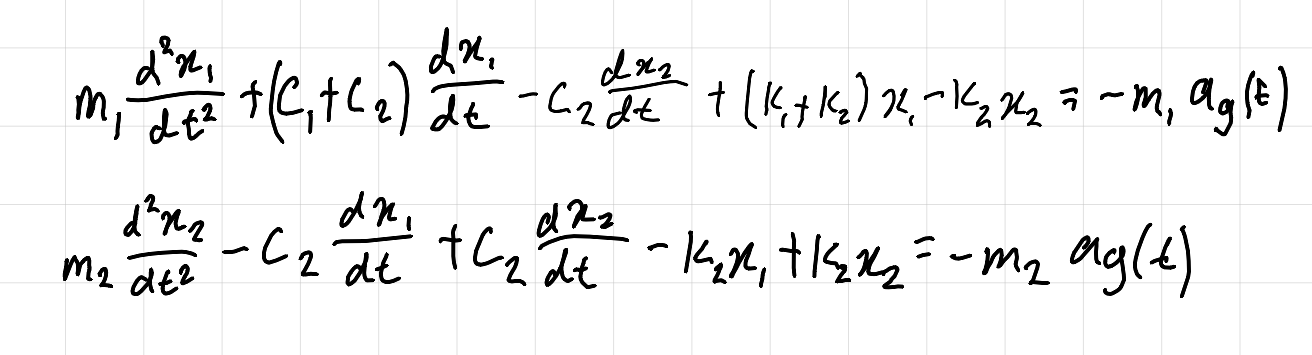

The equations of motion were taken fromthe beginning of Problem 1 and alterations were made to the notation in order to linearize these second order differential equations.Namely, dx1/dt was converted to y1, dx2/dt was converted to y2, and their corresponding derivatives  were converted to dy1/dt and dy2/dt respectively.

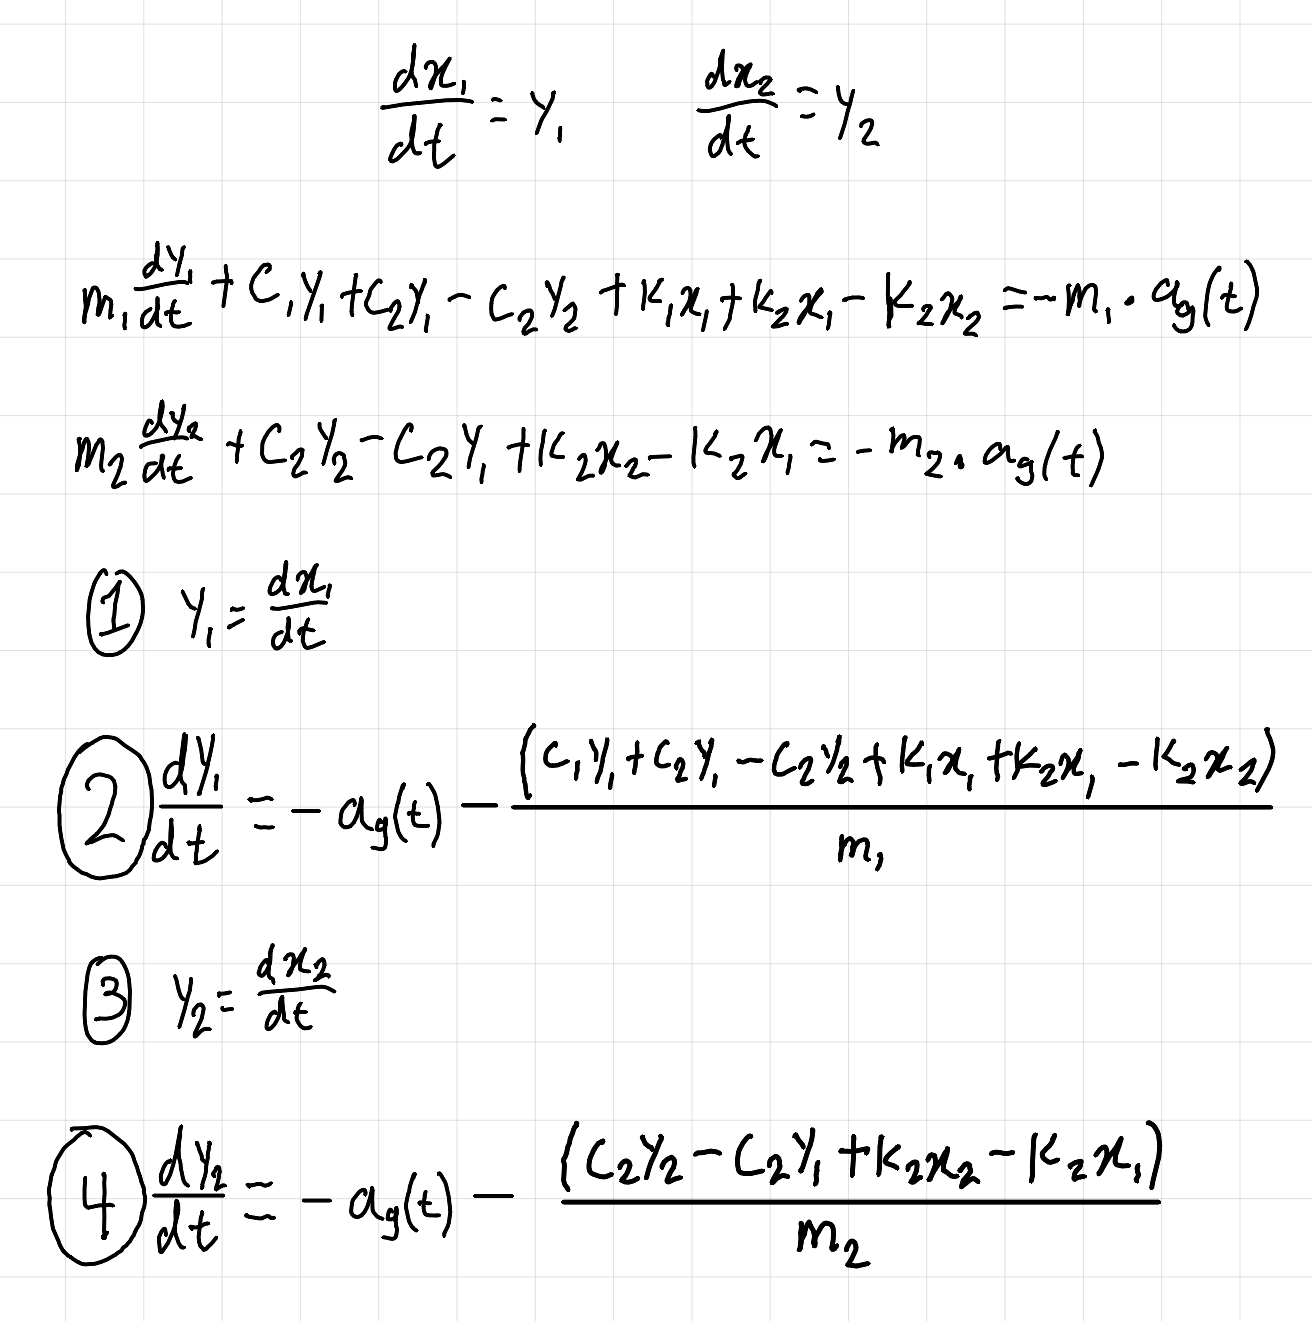

This led to the results presented in the figure above where equation 1 and equation 3 are simply y1 = dx1/dt and y2 = dx2/dt, while equations 2 and 4 are simply the values of dy1/dt and dy2/dt when isolated with respect to the equations of motion. These equations are also contained in the dy matrix in solution 1a. ii).

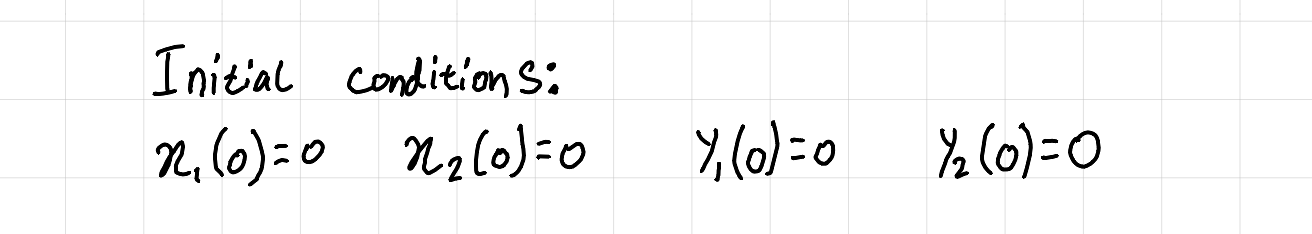

The Initial conditions are identical to the initial conditions which are provided in the instructions for problem 1.

#### Solution 1a ii)

% Initial Conditions

initial_conditions = [0; 0; 0; 0];


% Function governing ground acceleration

function a = ag(t) 
    g = 9.81;
    if t <= 5
        a = 0.30 * g * sin(8*t) * sin(pi*t/5)^2;
    else
        a = 0;
    end
end


% Function dy which contains the 4 governing equations

function dy = f(t, y)
    m1 = 20000;
    m2 = 15000;
    k1 = 8000000;
    k2 = 5000000;
    c1 = 120000;
    c2 = 80000;

    dy = [y(2);
          -ag(t) - (c1*y(2) + c2*y(2) - c2*y(4) + k1*y(1) + k2*y(1) - k2*y(3))/m1;
          y(4);
          -ag(t) - (c2*y(4) - c2*y(2) + k2*y(3) - k2*y(1))/m2];
end

### Problem 1b. Numerically simulate the seismic response (5 pts)

Numerically simulate the solution to the system using RK4 with step-size $h_{\text{ref}} = 10^{-4}$ over a time-inverval ranging from $t=0$ to $t=15s$. Plot the floor displacement for both floors. This solution will serve as the reference solution for the rest of the problem. 

# Solution 1b

h  = 0.0001;

max delta1 = 0 m


t0 = 0;

max delta2 = 0 m


tf = 15;

max a1abs = 0 m/s^2


max a2abs = 0 m/s^2


[t, y] = RK4(@f, initial_conditions, t0, h, tf);

max_delta1 = 0;
max_delta2 = 0;
max_a1abs = 0;
max_a2abs = 0;

for n = 1:length(t)

 % Floor Displacement
 delta1 = y(1, n);
 delta2 = y(3, n) - y(1, n);

 % Absolute Floor Acceleration
 dy = f(t(n), y(:, n));
 a1abs = dy(2) + ag(t(n));
 a2abs = dy(4) + ag(t(n));

 % Tracking Maximum Displacement & Absolute Floor Acceleration
 max_delta1 = max(max_delta1, abs(delta1));
 max_delta2 = max(max_delta2, abs(delta2));
 max_a1abs = max(max_a1abs, abs(a1abs));
 max_a2abs = max(max_a2abs, abs(a2abs));

end

figure
plot(t, y(1,:), t, y(3,:))
xlabel('Time (s)')
ylabel('Floor Displacement (m)')
legend('Floor 1', 'Floor 2')
title('Floor Displacement vs. Time')
grid on

Through the use of RK4, the floor displacement of both floors was approximated with a step sizes of h = 0.0001 from t = 0s to t = 15s. These displacements were then plotted on a displacement-time graph.

### Problem 1c. Compare different explicit methods (15 pts)

Numerically simulate the solution to the system using the explicit numerical methods introduced in the lectures (explicit Euler, improved Euler, and RK4) over a time period ranging from $t=0$ to $t=15s$ with different time-steps ( $h=0.005, 0.01, 0.05, 0.1$). Compare the floor displacements obtained with the different methods and discuss their accuracy and suitability for this problem, by comparing the computed solutions against the reference solution.

# Solution 1c

h  = [0.005, 0.01, 0.05, 0.1];

for i = 1:length(h)

    [t, y] = explicit_euler(@f, initial_conditions, t0, h(i), tf);

    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n);
    end


end

for i = 1:length(h)

    [t, y] = improved_euler(@f, initial_conditions, t0, h(i), tf);

    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n);
    end

end


for i = 1:length(h)

    [t, y] = RK4(@f, initial_conditions, t0, h(i), tf);

    max_delta1 = 0;
    max_delta2 = 0;
    max_a1abs = 0;
    max_a2abs = 0;

    for n = 1:length(t)

     % Floor Displacement
    delta1 = y(1, n);
    delta2 = y(3, n) - y(1, n);
    end

end

### Problem 1d. Numerically simulate the seismic response with implicit Euler. (10 pts)

i. Numerically simulate the solution to the system using implicit Euler over the same time period and with the same time-steps as in problem 1c. Derive the linear system that must be solved in each timestep (you may do this with hand-writing included as a picture) and discuss how the repeated solution of the resulting linear system can be implemented efficiently. 

ii. Discuss the accuracy and suitability of this method for this problem compared to the explicit methods from 1c. Use the same reference solution.

# Solution 1d

### Problem 1e. Evaluate response (5 pts)

Evaluate the seismic response of the reference building. Consider the floor displacements, interstory drifts, and absolute floor accelerations, and determine whether the building satisfies all the structural performance requirements. Discuss the relationship between structural stiffness, damping, interstory drift, floor acceleration, structural safety, and occupant comfort.

# Solution 1e

Utilizing the reference solution from 1b which utilizes RK4 with a step size of h = 0.0001, the displacement and absolute acceleration of both floors has already been simulated and recorded. Now, what is left is to analyze the obtained values and determine whether the building satisfies the structural performance requirements.

disp(['max delta1 = ', num2str(max_delta1), ' m'])
disp(['max delta2 = ', num2str(max_delta2), ' m'])
disp(['max a1abs = ', num2str(max_a1abs), ' m/s^2'])
disp(['max a2abs = ', num2str(max_a2abs), ' m/s^2'])

Both the maximum displacement of the first floor and the maximum displacement of the second floor fall within the allowable thresholds set out by the structural performance requirements. For this specific earthquake and reference building, both floors stay sufficiently close to their starting locations and the maximum displacement thresholds for both floors are satisfied. Furthermore, the interstory drift is minimal, ammounting to less that 0.05 meters in total.

This indicates that the stiffness of the building is sufficiently high, keeping the overall displacement below the critical thresholds. However, while a high stiffness has a reductive effect on the overall displacement, it also has the inverse relationship with respect to floor acceleration since the building exerts more force trying to return to its starting position. 

On the other hand, the absolute acceleration of the second floor (and in fact, the first floor as well) exceeds the limit of 4 m/s^2 set out by the structural performance requirements and reaches a maximum value of approximately 5.35 m/s^2 (and 4.3 m/s^2 for the first floor). This means that this third requirement is not satisfied and that the reference building does not properly account for the structural performance requirements since it is not constructed with the maximum acceleration criterion in mind.

The breach of the floor acceleration threshold negatively affects occupant comfort as the building rapidly accelerates the occupants in alternating directions in the event of an earthquake in addition to potentially damaging equipment within the building. While a reduction in the building stiffness would reduce the absolute floor acceleration, this would also increase the maximum floor displacement which could lead to structural damage; a better solution to the excessive absolute floor acceleration would be the inclusion of stronger dampers which would more actively dissipate the kinetic energy of the floors while they are in motion, thereby reducing the absolute floor acceleration experienced during an earthquake.

### Problem 1f. Challenging extension: building modifications (10 pts)

We will investigate the possibility of modifying the story stiffnesses to ensure the building meets all structural performance requirements. Consider multiplying both story stiffnesses by a common factor $$\alpha\geq1$$, so that $$k_1^{\mathrm{new}}=\alpha k_1$ and $k_2^{\mathrm{new}}=\alpha k_2$$. The goal of this exercise is to compute the smallest value of $\alpha$ that reaches the performance boundary. Use a root-finding method to find the smallest such $\alpha$. You may not use a built-in root-finding method, you must use your implementation of one of the algorithms discussed during the course. On each iteration of the root-finding algorithm, you will compute a new numerical simulation to the building response.

After you computed $\alpha$, repeat the simulation with the new story stiffnesses and verify that every performance requirement is satisfied.

# Solution 1f

## Problem 2: Transient Heat Transfer in a Cooling Fin (28 pts)

Cooling fins are commonly used to increase the transfer of heat between a hot surface and the surrounding environment. They are found in electronic cooling systems, engines, heat exchangers, and many other thermal systems.

Consider a straight rectangular fin attached to the surface of an electronic device. When the device is turned on, the temperature at the base of the fin increases. Heat is conducted along the fin and transferred from its surface to the surrounding air by convection.

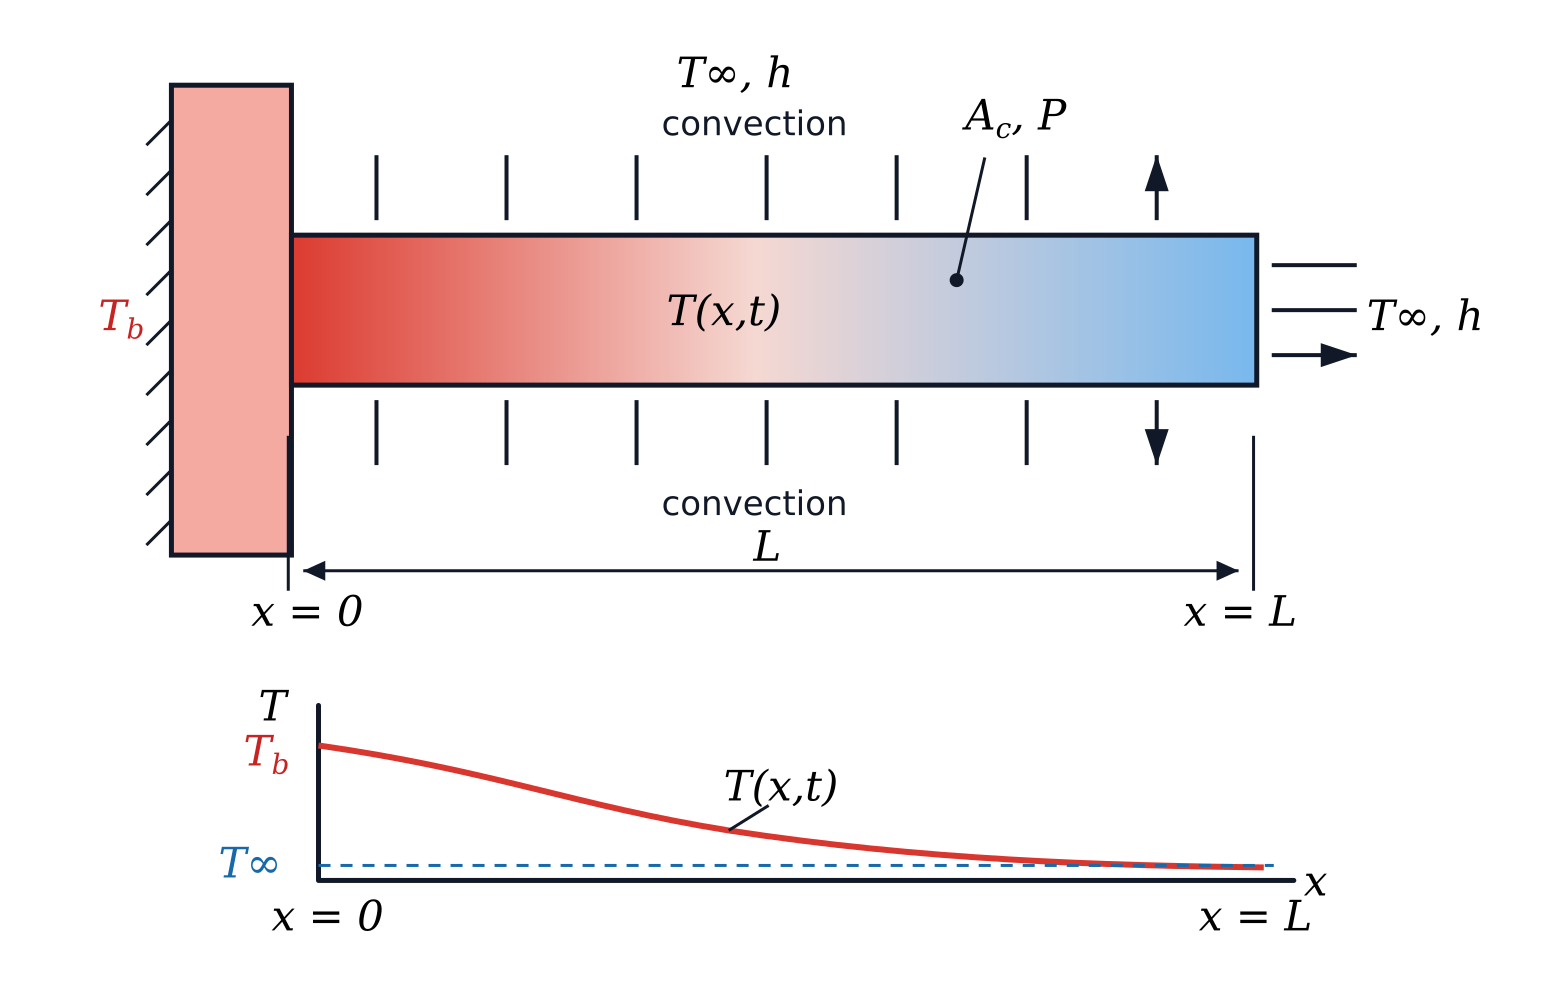

The temperature distribution in the fin is denoted by $T(x,t)$, where $x$ is the distance measured from the base of the fin and $t$ is time.

Assuming one-dimensional heat conduction, constant material properties, and uniform convection over the fin surface, the temperature is governed by


$$
 \rho c_p A_c
 \frac{\partial T}{\partial t}
 =
 kA_c\frac{\partial^2T}{\partial x^2}
 -hP\left(T-T_\infty\right)$$


for


$$
 0<x<L,
 \qquad
 0<t\leq t_{\mathrm{end}}$$


Equivalently,


$$
 \frac{\partial T}{\partial t}
 =
 \alpha\frac{\partial^2T}{\partial x^2}
 -\beta\left(T-T_\infty\right)$$


where


$$
 \alpha=\frac{k}{\rho c_p}
$$


is the thermal diffusivity and


$$
 \beta=\frac{hP}{\rho c_pA_c}
$$


represents the effect of convection from the lateral surface.

The parameters appearing in the model are:

- $k$: thermal conductivity

- $\rho$: material density

- $c_p$: specific heat capacity

- $h$: convective heat-transfer coefficient

- $A_c$: cross-sectional area of the fin

- $P$: exposed perimeter of the fin

- $T_\infty$: ambient temperature

- $L$: fin length

### Fin geometry and material properties

The reference fin is made of aluminum and has a rectangular cross-section.

Use the following parameters:

For a rectangular cross-section, the cross-sectional area is


$$
 A_c=wb$$


and the exposed perimeter is


$$
 P=2(w+b)$$


### Initial and boundary conditions

Initially, the fin is at the same temperature as the surrounding air:


$$
 T(x,0)=T_\infty=20^\circ\mathrm{C},
 \qquad
 0\leq x\leq L$$


The electronic device operates for 300 seconds. During this period, the base of the fin is maintained at


$$
 T_b=100^\circ\mathrm{C}$$


After 300 seconds, the device is switched off and the base temperature returns to the ambient temperature.

The base boundary condition is therefore


$$
 T(0,t)=T_b(t)$$


where


$$
 T_b(t)=
 \begin{cases}
 100^\circ\mathrm{C},
 &0<t\leq300\ \mathrm{s}\\[4pt]
 20^\circ\mathrm{C},
 &t>300\ \mathrm{s}
 \end{cases}
$$


Assume that heat transfer from the tip of the fin is negligible. Therefore, the tip is modeled as insulated:


$$
 \frac{\partial T}{\partial x}(L)
 =0$$


Simulate the temperature distribution over


$$
 0\leq t\leq900\ \mathrm{s}$$


This interval includes:

1. the transient heating of the fin

2. the approach toward a steady temperature distribution

3. the cooling process after the device is switched off

### Spatial discretization

Divide the spatial domain into $N$ intervals of equal length, such that the $N+1$ nodes are


$$
 x_i=i\Delta x,
 \qquad
 i=0,1,\ldots,N,
$$


where


$$
 \Delta x=\frac{L}{N}$$


The temperature at node $x_i$ and time $t_n$ is approximated by


$$
 T_i^n\approx T(x_i,t_n)$$


Use a second-order central difference approximation for the spatial derivative and explicit Euler for the time derivative.

### Problem 2a. Derive finite-difference approximation (4 pts)

Discretize the spatial domain using central finite differences and incorporate the initial and boundary conditions. Explain how the insulated-tip condition is applied at $$x=L$$. You may use a picture of a hand-written derivation.

# Solution 2a (no code)

### Problem 2b. Numerically simulate a solution (5 pts)

Compute a numerical solution to the transient heat-transfer problem. Use a suitable spatial step-size and a time-step size and simulate the complete heating and cooling cycle. Do not use built-in partial differential equation solvers.

# Solution 2b

### Problem 2c. Investigate stability region (5 pts)

Select $  $$
  \Delta x=0.005\ \mathrm{m}
  $$$ and investigate how the computed solution is affected by the time step-size. For this problem, an approximate stability requirement for explicit Euler is


$$  $$
  \Delta t
  \leq
  \frac{1}
  {
  \frac{2\alpha}{\Delta x^2}+\beta
  }
  $$
$$


Compare the theoretical stability restriction with the behavior observed in the numerical simulations.

# Solution 2c

### Problem 2d. Investigate heating and cooling (6 pts)

i. Use


$$  $$
  \Delta x=0.005\ \mathrm{m}
  $$$$


and an appropriate time-step size. Plot the temperature distribution at


$$  $$
  t=0,\ 30,\ 100,\ 300,\ 450,\ 600,\ 900\ \mathrm{s}
  $$$$


The selected times should clearly demonstrate the heating stage, the moment at which the device is switched off, and the subsequent cooling stage. Plot the solutions in the heating stage in one plot and the solutions in the cooling stage in one plot.

ii. After the electronic device is switched off at $$t=300\ \mathrm{s}$$, determine the time required for the entire fin to cool below


$$  $$
  30^\circ\mathrm{C}
  $$$$


Define the cooling time as the first time after $$t=300\ \mathrm{s}$$ for which

$  $$
  \max_{0\leq x\leq L}T(x,t)
  <
  30^\circ\mathrm{C} $$$.

# Solution 2d

### Problem 2e. Challenging extension: e**valuate the thermal performance (8 pts)**

i. Calculate the heat-transfer rate from the base into the fin using


$$  $$
  \dot{Q}_b(t)
  =
  -kA_c
  \left.
  \frac{\partial T}{\partial x}
  \right|_{x=0}
  $$$$


Approximate the temperature gradient at the base using an appropriate finite-difference formula.

ii. Calculate the total thermal energy transferred to the fin during the operation of the device:


$$  $$
  E_{\mathrm{transferred}}
  =
  \int_0^{300}
  \dot{Q}_b(t)\,dt
  $$$$


Approximate the time integral using a suitable numerical integration method.

# Solution 2e